% 1. Generate 2500 pseudo-random numbers on (0,1) using LCG Method
clear;
clc;

M = 2500;
ID = 801201076;
disp('N = '); disp(mod(ID,3));

N = 
     1




[A,p1] = lcgg(M,30269,171,0,1);
[B,p2] = lcgg(M,30307,172,0,1);
[C,p3] = lcgg(M,30323,170,0,1);

disp('Period = '); disp(p2);

Period = 
       30306



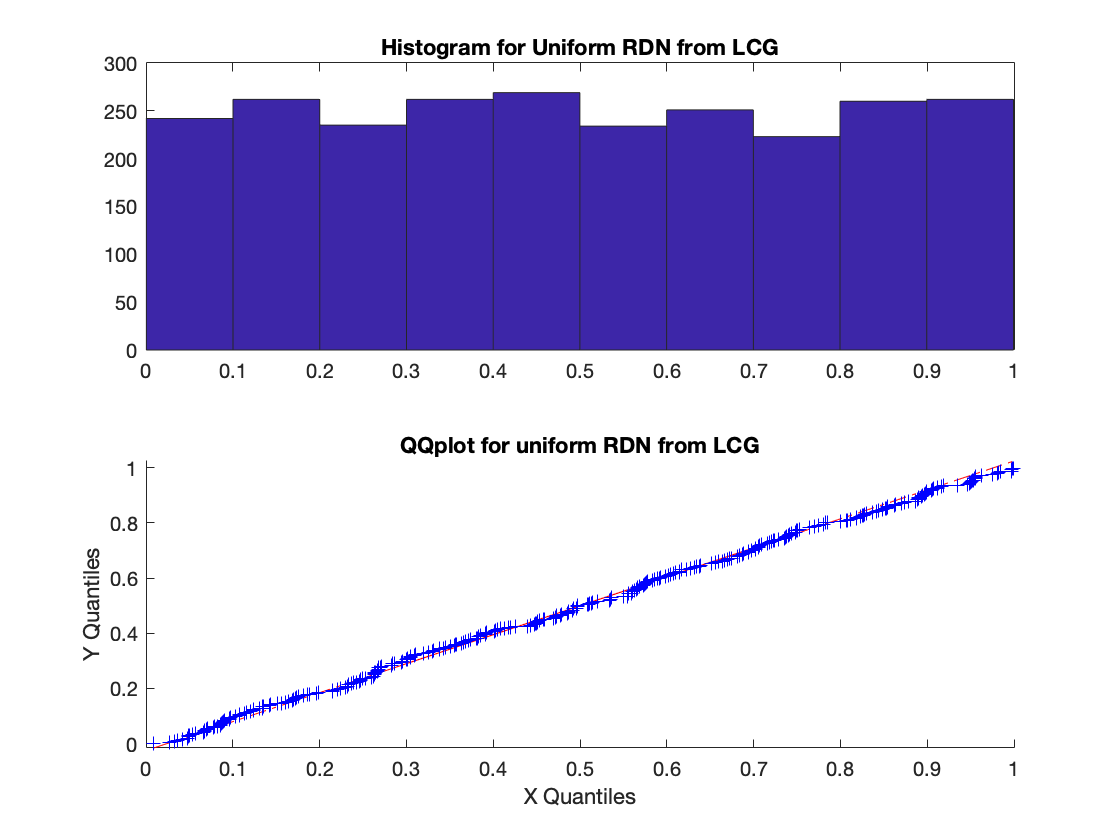


% Combine the 3 generators as in Wichmann and Hill
figure(1);
subplot(2,1,1);hist(B);title('Histogram for Uniform RDN from LCG');
subplot(2,1,2);qqplot(rand(300,1),B);title('QQplot for uniform RDN from LCG');

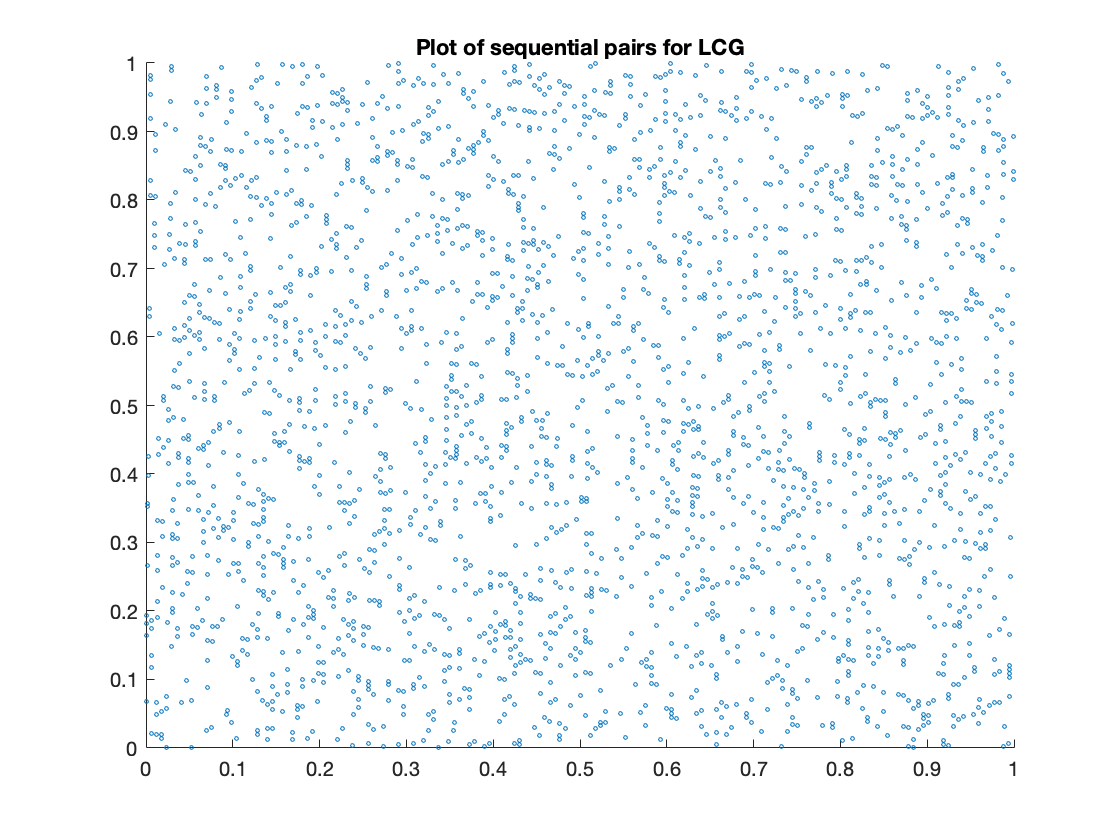


figure(2);
scatter(B(1:(M-1),1),B(2:M,1),4);title('Plot of sequential pairs for LCG');

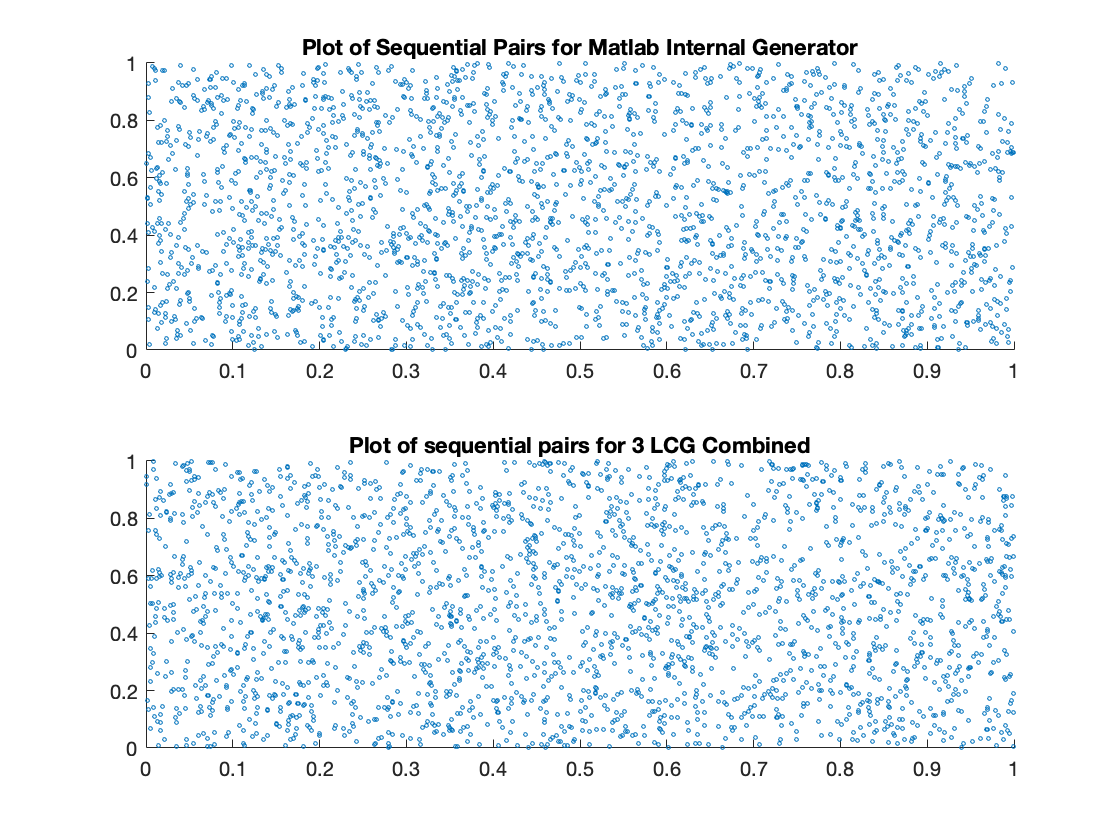


D = A + B + C - fix(A + B + C); % internal Matlab uniform random number generator

u = rand(M,1); % internal Matlab uniform random number generator

figure(3);
subplot(2,1,1);scatter(u(1:(M-1),1),u(2:M,1),4);title('Plot of Sequential Pairs for Matlab Internal Generator');
subplot(2,1,2);scatter(D(1:(M-1),1),D(2:M,1),4);title('Plot of sequential pairs for 3 LCG Combined')



% Question 2: Implement Normal random number generator using inverse
% transform method.

% Normal random number using inverse transform method
D = rand(M,1); %uniform
X = zeros(M,1);

for i=1:M  
    X(i,1) = inv_norm(D(i,1)); %normal
end
disp('Mean: '); disp(mean(X));

Mean: 
   -0.0093



disp('STD: '); disp(sqrt(var(X)));

STD: 
    1.0006



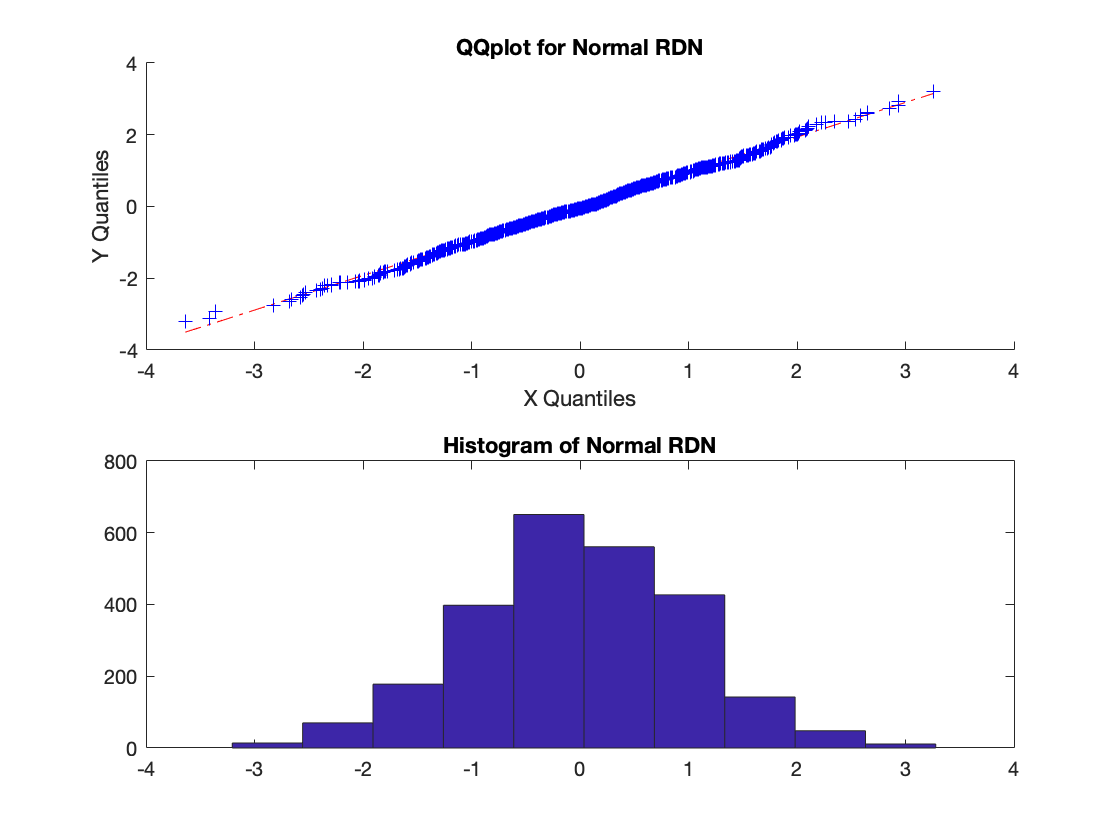


figure(4);
subplot(2,1,1);qqplot(randn(1000,1),X);title('QQplot for Normal RDN');
subplot(2,1,2);hist(X);title('Histogram of Normal RDN');

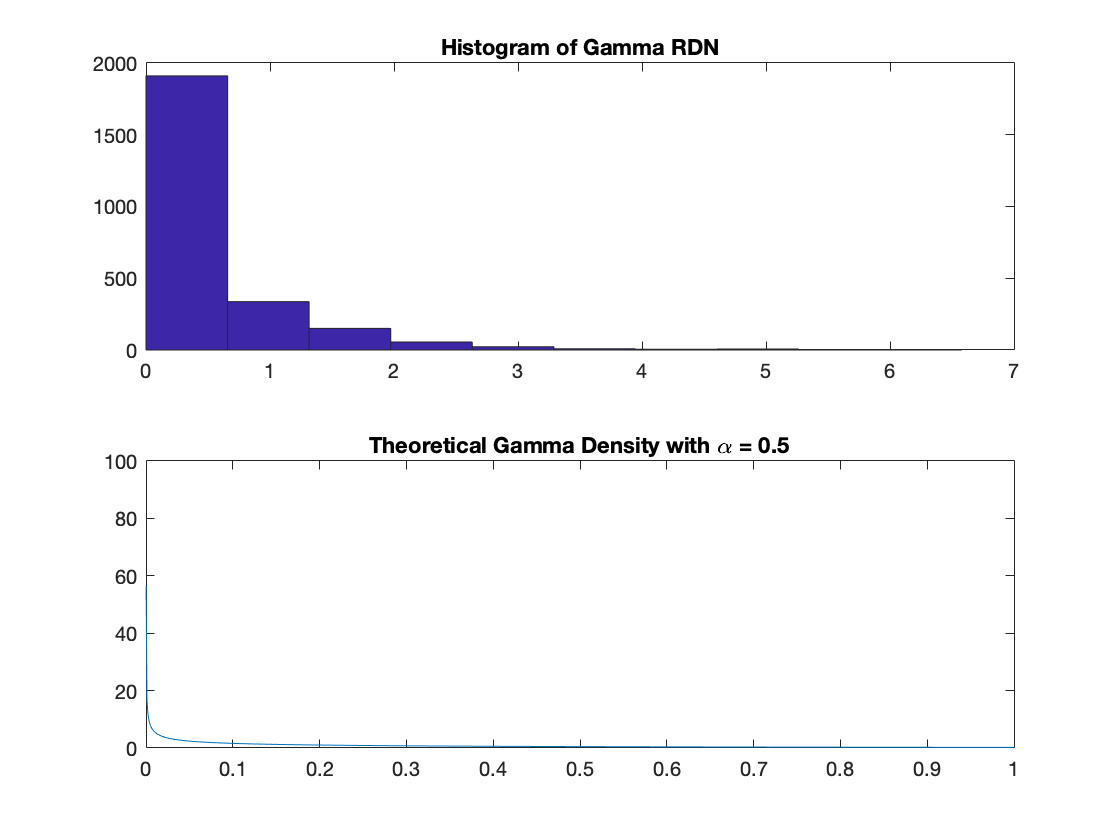

 

% Question 2B. Gamma distribution for alpha <= 1 using composition, inverse
% transform and accept-rejection method
% Ref: GS Fishman
alpha = 0.5;
w = gamma_rdn(M,alpha);
x1 = (0.0001:0.001:1); % For plot

figure(5)
subplot(2,1,1);hist(w);title('Histogram of Gamma RDN');
subplot(2,1,2);plot(x1,pdf('gam',x1,alpha,1));title('Theoretical Gamma Density with \alpha = 0.5');
axis([0 1 0 100]);

function[A,p] = lcgg(M,m,a,c,x0)
    % Generates a matrix of random numbers using lcg
    % Calculate the period
    % Input: M: total number of random numbers needed
    %         m, a, x, x0
    % Output: A: M * 1 matrix of random numbers
    %         p: period of the LCG random number generator
    A = zeros(m,1);
    for i = 1:m
        if i == 1
            A(i,1) = lcg(m,a,c,x0);
        else
            A(i,1) = lcg(m,a,c,A(i-1,1));
        end
    end 
    
    % Calculate the period
    i = 1;
    j = 2;
    while A(i,1) ~= A(j,1) && i < m
        if j < m
            j = j+1;
        else
            i = i+1;
            j = j+1;
        end
    end
    if i == m
        p = m;
    else
        p = j-1;
    end
    A = A./m;
    if M <= m
        A = A(1:M,:);
    end
end


% The LCG Function:
function[x] = lcg(m,a,c,x0)
    % Linear Congruential Generator (LCG)
    x = mod(a*x0+c, m);
end


% The inv_norm function is as follows:
function[x] = inv_norm(u)
    % Invert the CDF of normal Phi(x)
    % reference;
    % Paul Glasserman, P. 67-68
    % Use inv_norm(cdf('norm',1.96,0,1)) to test
    a0 = 2.50662823884;
    a1 = -18.61500062529;
    a2 = 41.39119773534;
    a3 = -25.44106049637;
    b0 = -8.47351093090;
    b1 = 23.08336743743;
    b2 = -21.06224101826;
    b3 = 3.13082909833;
    c0 = 0.3374754822726147;
    c1 = 0.9761690190917186;
    c2 = 0.1607979714918209;
    c3 = 0.0276438810333863;
    c4 = 0.0038405729373609;
    c5 = 0.0003951896511919;
    c6 = 0.0000321767881768;
    c7 = 0.0000002888167364;
    c8 = 0.0000003960315187;
    
    y = u - 0.5;
    if y == 0
        x = 0;
    elseif abs(y) < 0.42 
        r = y*y;
        x = y*(a0+r*(a1+r*(a2+r*a3)))/(1+r*(b0+r*(b1+r*(b2+r*b3))));
    else
        r = u;
        if y > 0
            r = 1 - u;
        end
        r = log(-log(r));
        x = c0+r*(c1+r*(c2+r*(c3+r*(c4+r*(c5+r*(c6+r*(c7+r*c8)))))));
        if y < 0
            x = -x;
        end
    end
end


% The gamma_rdn function is implemented as follows:
function[w] = gamma_rdn(M,alpha)
    % Generate random numbers from the gamma distribution with parameter
    % alpha <= 1, beta = 1
    pe = exp(1);
    w = zeros(M,1);
    u = rand(10000,1); % Had to choose a value higher than 100 in rand() as 
    % I was receiving errors for it exceeding array bounds at 100 and y was
    % was becoming invalid due to an 'i' value being too large passed into
    % u().
    b = (alpha + pe)/pe;
    i = 0;
    j = 0;
    while j < M
        i = i+1;
        y = b*u(i,1);
        if y <= 1
            z = y^(1/alpha);
            i = i+1;
            if u(i,1) <= exp(-z)
                j = j+1;
                w(j,1) = z;
            else
                i = i+1;
            end
        else
            z = -log((b-y)/alpha);
            i = i+1;
            if u(i,1) <= z^(alpha - 1)
                j = j+1;
                w(j,1) = z;
            else
                i = i+1;
            end
        end
    end
    if i > 95
        u = rand(10000,1);
        i = 0;
    end
end